# **Detecció de presència de jugadors del Barça en la escena.**

### **1.**Seleccioneu una (o més) imatges on apareguin jugadors del Barça, que serviran de model.

Im = imread("imatges_equips\barcelona\01.jpg");
imshow(Im);

### Seleccioneu manualment un (o més) fragments de la imatge que continguin una part significativa de la samarreta.

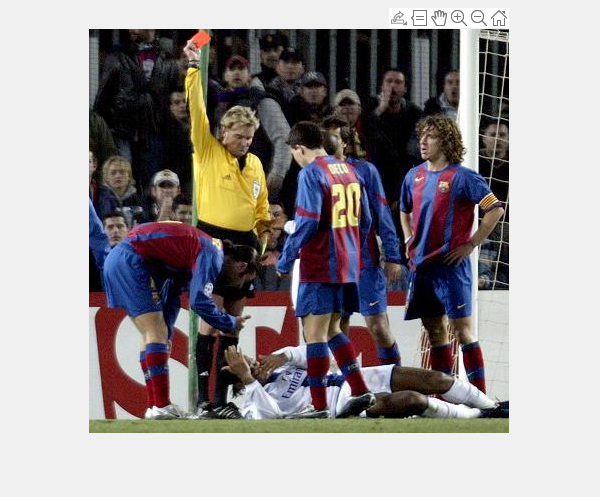

rect = getrect;

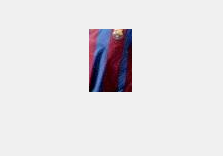

Im2 = imcrop(Im,rect);
imshow(Im2);

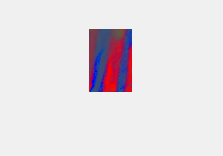

Im2 = normalitzar(Im2);
imshow(Im2);

### 2.Calculeu l’histograma de color dels fragments dels models. Aquests seran els histogrames model que usareu per buscar la samarreta en noves imatges.

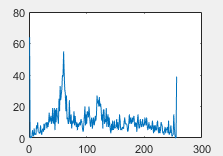

R = Im2(:,:,1);
G = Im2(:,:,2);
B = Im2(:,:,3);
hR = imhist(R);
hG = imhist(G);
hB = imhist(B);
plot(hR);

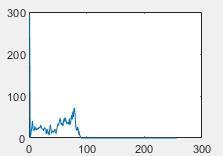

plot(hG);

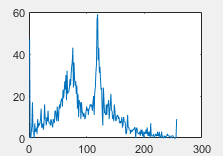

plot(hB);

### 3.Construïu histogrames de color de fragments de totes les imatges de tots els equips. Aquests fragments no poden ser seleccionats de forma manual, s'han de seleccionar de forma exhaustiva mitjançant finestra lliscant o de forma aleatòria

%filtrar imatge

### 4. Compareu aquests histogrames obtinguts, amb els histogrames model

%distance Euclidean / ChiSquare

### 5. A partir dels resultats de les comparacions determinar en quines imatges apareix la samarreta del Barça

### 6. Per a fer l'histograma, useu primer l'espai RGB i després repetiu l'experiment usant l'espai HSV. Compareu els resultats

#### *Auxiliar functions*

function [Norm] = normalitzar(Im)
 R = double(Im(:,:,1));
 G = double(Im(:,:,2));
 B = double(Im(:,:,3));
 I = (R+G+B);
 r = R./I;
 g = G./I;
 b = B./I;
 Norm = cat(3,r,g,b);
end
    
function [Filtrat] = selectFragments(Im) 
    R = Im(:,:,1);
    G = Im(:,:,2);
    B = Im(:,:,3);
    
    
end